data =    22.5661  113.9808   66.0000         0
   22.6862  113.9405   65.5000         0
   22.5765  113.9572   65.5000    1.0000
   22.5648  114.2446   75.0000         0
   22.5589  113.9507   65.5000         0
   22.5590  114.2413   75.0000         0
   22.5490  113.9723   65.5000    1.0000
   22.5628  113.9566   65.5000         0
   22.5000  113.8957   66.0000         0
   22.5438  113.9240   66.0000    1.0000

data_location =    22.5661  113.9808
   22.6862  113.9405
   22.5765  113.9572
   22.5648  114.2446
   22.5589  113.9507
   22.5590  114.2413
   22.5490  113.9723
   22.5628  113.9566
   22.5000  113.8957
   22.5438  113.9240

data = xlsread("附件一：已结束项目任务数据.xls")
data_location = data(:,1:2)
[num,text,raw]=xlsread("附件二：会员信息数据.xlsx")

num =    1.0e+04 *
    0.0114    0.0000    6.7997
    0.0163    0.0000    3.7927
    0.0139    0.0000    2.7953
    0.0098    0.0000    2.5086
    0.0066    0.0000    2.0919
    0.0072    0.0000    1.8238
    0.0015    0.0000    1.5729
    0.0095    0.0000    1.4868
    0.0110    0.0000    1.3556
    0.0064    0.0000    1.3328

text = 1878×5 cell array
    '会员编号'    '会员位置(GPS)'             '预订任务限额'    '预订任务开始时间'    '信誉值'
    'B0001'      '22.947097 113.679983'     ''              ''                 ''     
    'B0002'      '22.577792 113.966524'     ''              ''                 ''     
    'B0003'      '23.192458 113.347272'     ''              ''                 ''     
    'B0004'      '23.255965 113.31875'      ''              ''                 ''     
    'B0005'      '33.65205 116.97047'       ''              ''                 ''     
    'B0006'      '22.262784 112.79768'      ''              ''                 ''     
    'B0007'      '29.560903 106.239083'     ''              ''                 ''     
    'B0008'      '23.143373 113.376315'     ''              ''                 ''     
    'B0009'      '23.28528 113.651842'      ''              ''                 ''     
    'B0010'      '23.099259 113.488909'     ''              ''                 ''     
    'B0011'      '23.192462 113.347

raw = 1879×5 cell array
    '会员编号'    '会员位置(GPS)'             '预订任务限额'    '预订任务开始时间'    '信誉值'     
    'B0001'      '22.947097 113.679983'     [       114]    [       0.2708]    [6.7997e+04]
    'B0002'      '22.577792 113.966524'     [       163]    [       0.2708]    [3.7927e+04]
    'B0003'      '23.192458 113.347272'     [       139]    [       0.2708]    [2.7953e+04]
    'B0004'      '23.255965 113.31875'      [        98]    [       0.2708]    [2.5086e+04]
    'B0005'      '33.65205 116.97047'       [        66]    [       0.2708]    [2.0919e+04]
    'B0006'      '22.262784 112.79768'      [        72]    [       0.2708]    [1.8238e+04]
    'B0007'      '29.560903 106.239083'     [        15]    [       0.2708]    [1.5729e+04]
    'B0008'      '23.143373 113.376315'     [        95]    [       0.2792]    [1.4868e+04]
    'B0009'      '23.28528 113.651842'      [       110]    [       0.2750]    [1.3556e+04]
    'B0010'      '23.099259 113.488909'     [        64]    [       0.275

R = regexp(text(2:length(text),2)," ","split")

R = 1877×1 cell array
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
    {1×2 cell}
   

usrGeo = zeros(length(R),2);
for t=1:length(R)
    usrGeo(t,1) = str2double(R{t}{1});
    usrGeo(t,2) = str2double(R{t}{2});
end
usrGeo(1175,:)=[]

usrGeo =    22.9471  113.6800
   22.5778  113.9665
   23.1925  113.3473
   23.2560  113.3187
   33.6521  116.9705
   22.2628  112.7977
   29.5609  106.2391
   23.1434  113.3763
   23.2853  113.6518
   23.0993  113.4889

f = figure

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties

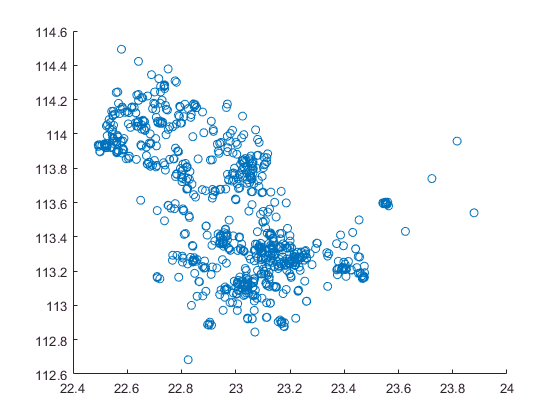

scatter(data_location(:,1),data_location(:,2),'o')

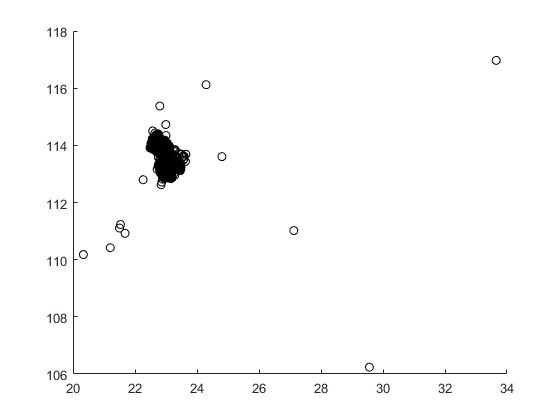

figure(f)
scatter(usrGeo(:,1),usrGeo(:,2),'ok')